# Linear Chirp  %线性调频信号

Generate a chirp with linear instantaneous frequency deviation. The chirp is sampled at 1 kHz for 2 seconds. The instantaneous frequency is 0 at *t* = 0 and crosses 250 Hz at *t* = 1 second.

t = 0:1/1e3:2; %fs=1e3（即 1000),信号的采样率（单位：Hz）
y = chirp(t,0,1,250);

Compute and plot the spectrogram of the chirp. Divide the signal into segments such that the time resolution is 0.1 second. Specify 99% of overlap between adjoining segments and a spectral leakage of 0.85.

%    计算并绘制线性调频信号（chirp）的频谱图。将信号划分为若干段，使时间分辨率为0.1秒。指定相邻段之间有99%的重叠率，以及频谱泄漏（spectral leakage ）为0.85。 

%   time  resolution    时间分辨率

%    overlap重叠

%   spectrogram   频谱图

%   adjoin”  “邻接；毗连；与…… 接壤” 。

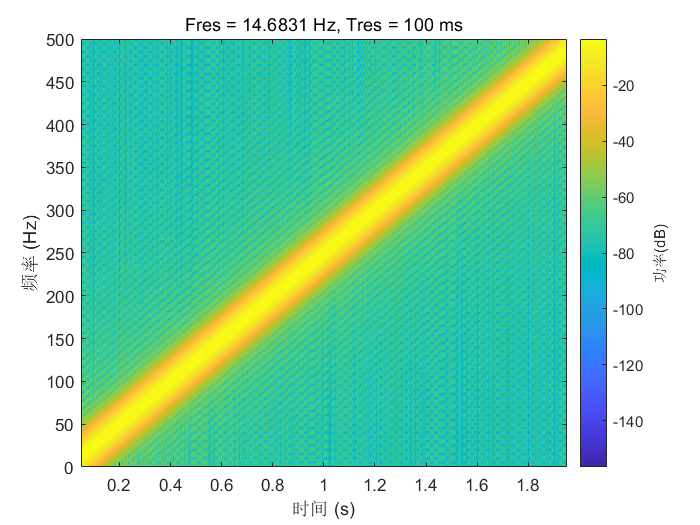

pspectrum(y,1e3,'spectrogram','TimeResolution',0.1, ...
    'OverlapPercent',99,'Leakage',0.85)  %99%的重叠  %频谱泄漏为0.85 %时间分辨率为0.1秒

                                         %1e3（即 1000）：信号的采样率（单位：Hz）

*Copyright 2015 The MathWorks, Inc.*